%{
ES 115 CLASS PROJECT PROBLEM 8.0
PROBLEM TITLE: Vehicle Fuel Consumption
DESCRIPTION: This project simulates vehicle fuel consumption over two types
             of driving styles by modeling speed as a function over time. Fuel usage is
             estimated based on vehicle speed, acceleration, and engine load, allowing
             analysis of how driving behavior affects total fuel consumption and
             efficiency.
PURPOSE: To estimate total fuel consumption over a driving cycle and
         analyze how variations in speed, accelerations, and engine load affect fuel
         efficiency.
INPUTS:
    ~ Time vector
    ~ Vehicle speed profile
    ~ Fuel consumption model parameters
    ~ Time step
OUTPUTS:
    ~ Speed vs Time
    ~ Fuel consumption rate vs time
    ~ Total fuel consumed
    ~ Fuel efficiency trends
ENGINNERING ALGORITHMS:
- Define time vector and driving cycle parameters
- Generate vehicle speed profiles over time
- Compute acceleration from speed data
- estimate fuel consumption
- Integrate fuel rate over time to obtain total fuel used and plot results

MATLAB TOOLS/FUNCTIONS:
- Vectorization
- Numerical Methods
- Signal Modeling
%}


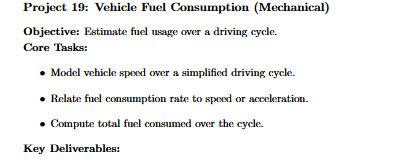

Choose driving style:


1 = Smooth Driving


2 = Aggressive Driving


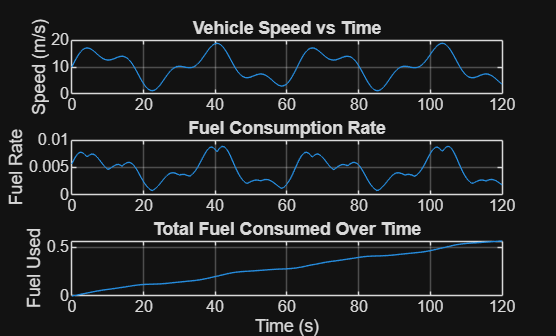


--- Fuel Consumption Results ---


Total Fuel Consumed: 0.5646 units


Total Distance Traveled: 1228.91 m


Fuel Efficiency: 2176.43 m per unit fuel


clc; clear; close all

% TIME VECTOR
t = 0:0.5:120;   % 2-minute driving cycle
% Time step used for numerical derivatives/integration
dt = 0.5;
% USER INPUT: Driving Style
disp('Choose driving style:')
disp('1 = Smooth Driving')
disp('2 = Aggressive Driving')
% Prompt user to select driving behavior
choice = input('Enter choice (1 or 2): ');
% SPEED PROFILE (Improved realistic model)
% Build speed profile matching chosen driving style
if choice == 1
    % Smooth driving
    v = 10 + 3*sin(0.05*t);
else
    % Aggressive driving
    v = 10 + 6*sin(0.2*t) + 3*sin(0.5*t);
end
% Prevent negative speeds from numerical model
v(v < 0) = 0;
% ACCELERATION
% Numerical derivative of speed (m/s^2)
a = gradient(v, dt);
% IMPROVED FUEL CONSUMPTION MODEL
a0 = 0.0005;
a1 = 0.0002;
a2 = 0.00001;
a3 = 0.0003;
a4 = 0.00005; % added interaction term
% Empirical fuel-rate model including speed-accel interaction
fuel_rate = a0 + a1*v + a2*v.^2 + a3*abs(a) + a4*(v.*abs(a));
% TOTAL FUEL USED
fuel_total = trapz(t, fuel_rate);
% DISTANCE AND FUEL EFFICIENCY
distance = trapz(t, v);
% Efficiency metric: distance per unit fuel
fuel_efficiency = distance / fuel_total;
% CUMULATIVE FUEL
fuel_cumulative = cumtrapz(t, fuel_rate);
% PLOTS
figure
subplot(3,1,1)
plot(t, v)
title('Vehicle Speed vs Time')
ylabel('Speed (m/s)')
grid on
subplot(3,1,2)
plot(t, fuel_rate)
title('Fuel Consumption Rate')
ylabel('Fuel Rate')
grid on
subplot(3,1,3)
plot(t, fuel_cumulative)
title('Total Fuel Consumed Over Time')
ylabel('Fuel Used')
xlabel('Time (s)')
grid on
% OUTPUT RESULTS
fprintf('\n--- Fuel Consumption Results ---\n')
fprintf('Total Fuel Consumed: %.4f units\n', fuel_total);
fprintf('Total Distance Traveled: %.2f m\n', distance);
fprintf('Fuel Efficiency: %.2f m per unit fuel\n', fuel_efficiency);